**FIRST READ THE DATA SET (CSV FORMAT)**

clc %clears the command window
close all %close all windows
clear all %clears the workspace

Path = '/Users/mac/Desktop/FYP/Code and Data/Data Collection/';
warning("off")

colaccX = 3;
colaccY = 4;
colaccZ = 5;

colgyroX = 10;
colgyroY = 11;
colgyroZ = 12;

colgravX = 21;
colgravY = 22;
colgravZ = 23;

M = 64;

## **Forehands (my data)**

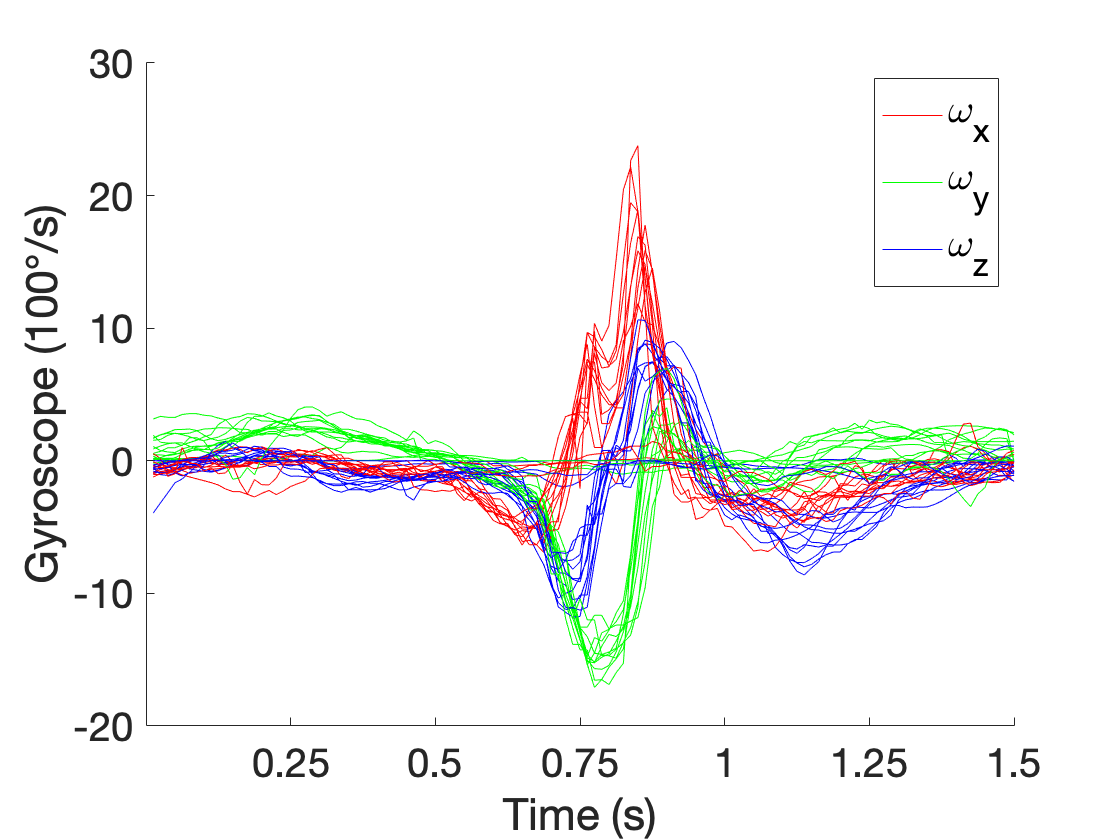

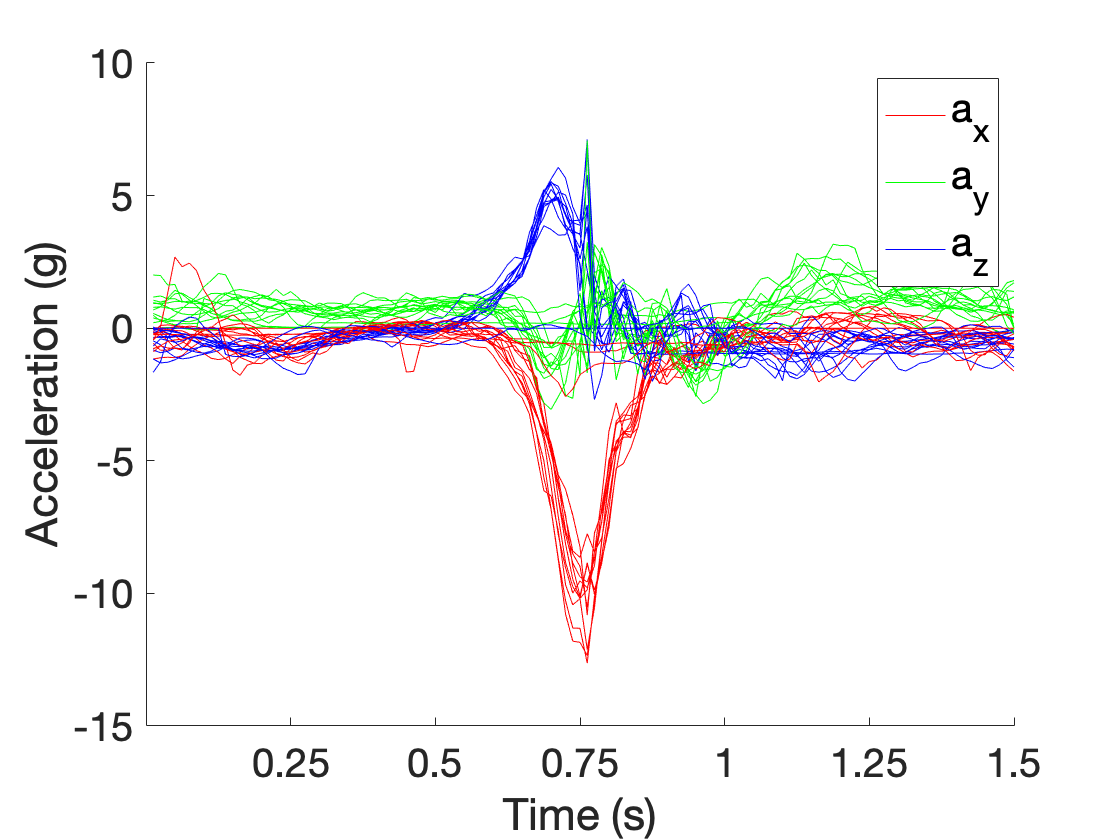

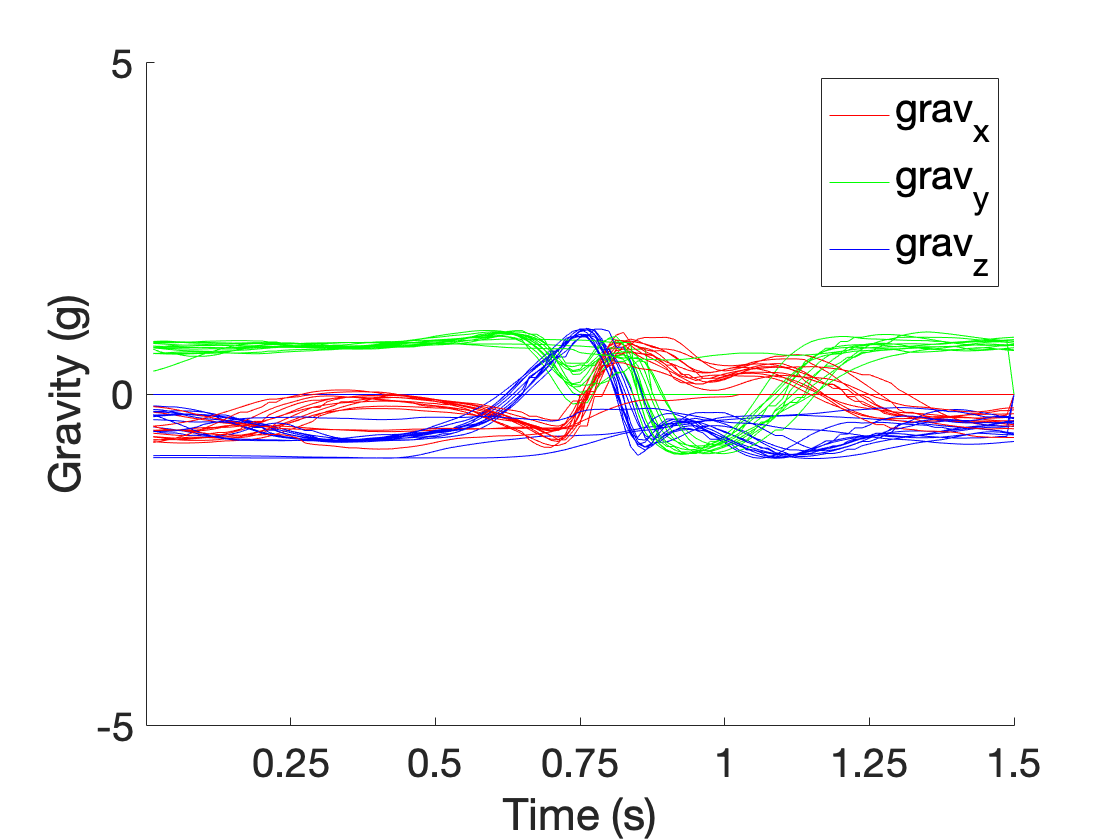

Filename1 = string(Path) + 'Player 17/M.Me.Fd.17.1.csv';
Filename2 = string(Path) + 'Player 17/M.Me.Fd.17.2.csv';
Filename3 = string(Path) + 'Player 17/M.Me.Fd.17.3.csv';
Filename11 = string(Path) + 'Player 23/M.Me.Fd.23.1.csv';
Filename12 = string(Path) + 'Player 23/M.Me.Fd.23.2.csv';

files_fd = [Filename1, Filename2, Filename3, Filename11, Filename12];

[AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ] = Compile_trial(files_fd, M, colaccX,colaccY,colaccZ,colgyroX,colgyroY,colgyroZ,colgravX,colgravY,colgravZ);

[faMax,faMin,faMean,faStd,faArea,fgMax,fgMin,fgMean,fgStd,fgArea,fgravMax,fgravMin,fgravMean,fgravStd,fgravArea] = MaxMin_trial(AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ);
[RacketSpeedAverage] = RacketSpeed(AllfGyroY, AllfGyroZ);

RacketSpeedAverage = 36.8652

[GmeanY,GareaY] = followthrough(AllfGyroY,AllfGyroZ)

GmeanY =    -0.1284   -3.4488   -3.3960   -3.2225   -3.6017   -3.6712   -2.8814   -3.2116   -3.0338         0   -0.6791   -2.7317   -2.2169   -2.5005   -0.6607


GareaY =    -5.0262 -139.1971 -139.1146 -130.5999 -146.2151 -149.3728 -116.6185 -129.7167 -122.4908         0  -27.4270 -111.9815  -88.4191 -100.4424  -27.5971


## Forehand NO FOLLOW-THROUGH

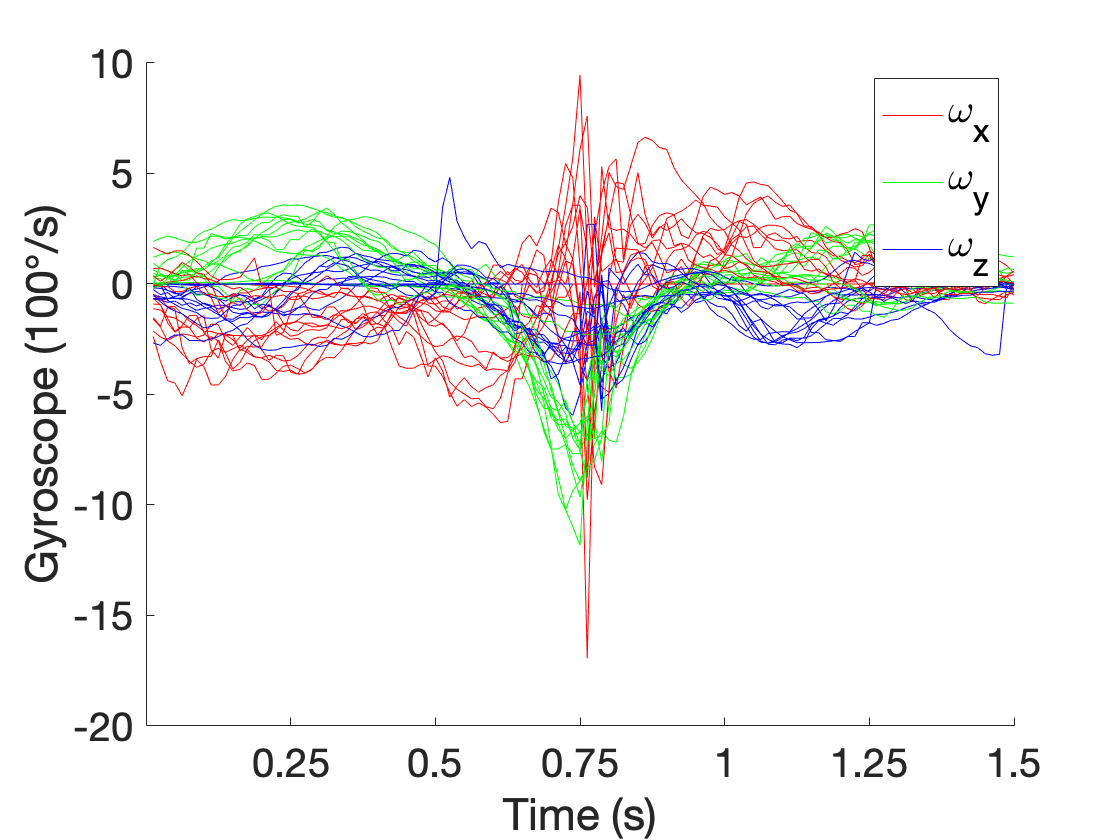

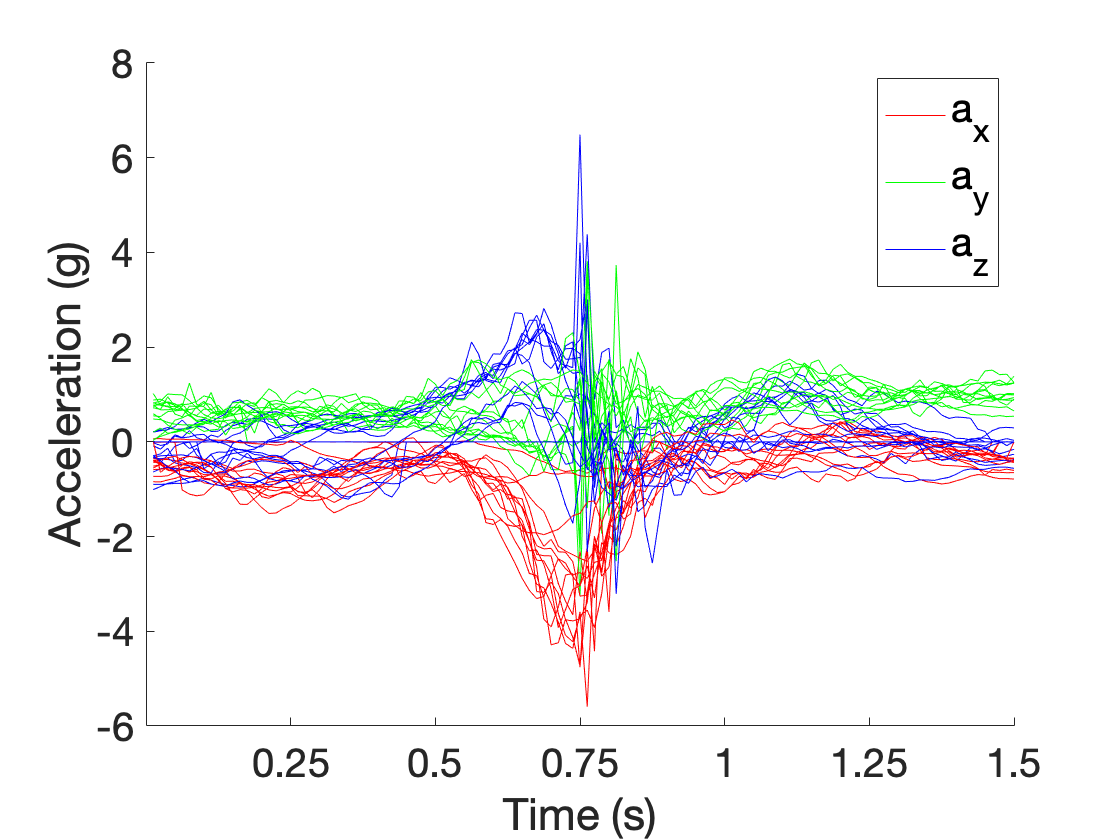

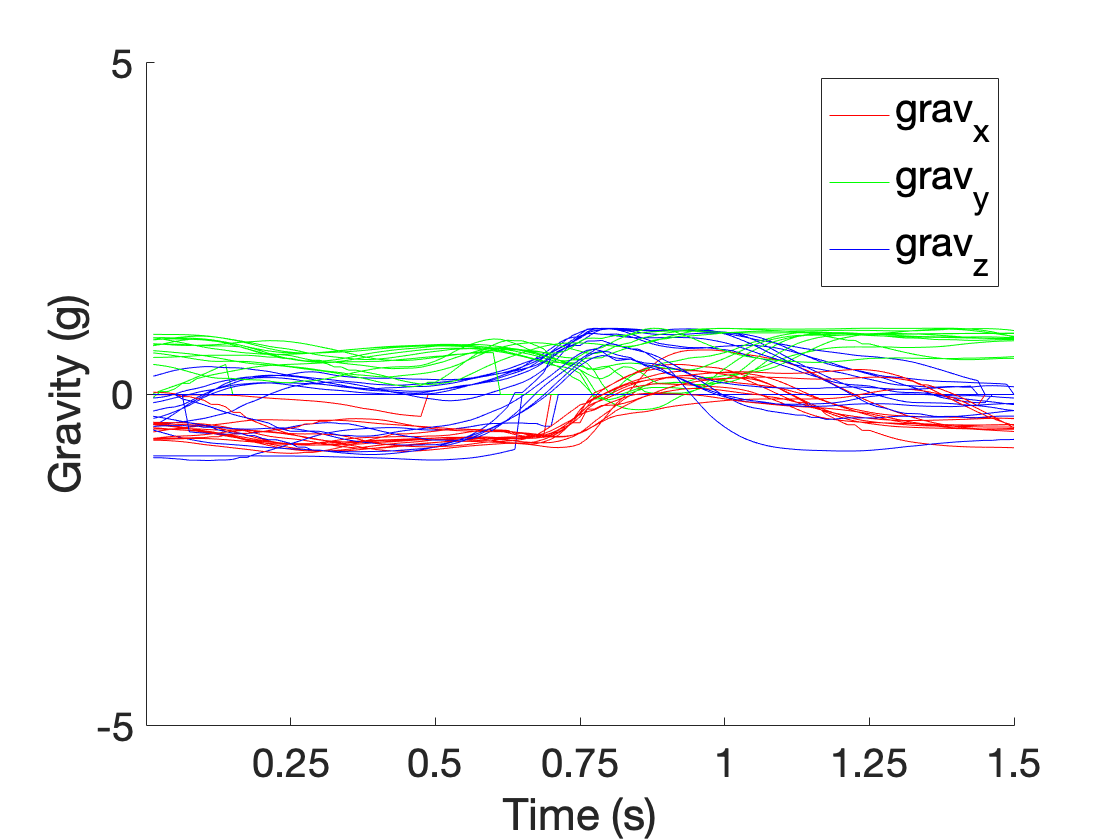

Filename1= string(Path) + 'Player 29/F.B.Fd.NOFT.1.csv';% Disha
Filename4= string(Path) + 'Player 29/F.B.Fd.NOFT.2.csv';% Disha
Filename5= string(Path) + 'Player 29/F.B.Fd.NOFT.3.csv';% Disha
Filename2= string(Path) + 'Player 30/F.B.Fd.NOFT.1.csv';% Hannah
Filename3= string(Path) + 'Player 30/F.B.Fd.NOFT.2.csv';% Katarina

files_fd_No_followthrough = [Filename1, Filename2, Filename3, Filename4,Filename5];

[AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ] = Compile_trial(files_fd_No_followthrough,M, colaccX,colaccY,colaccZ,colgyroX,colgyroY,colgyroZ,colgravX,colgravY,colgravZ);

[faMax,faMin,faMean,faStd,faArea,fgMax,fgMin,fgMean,fgStd,fgArea,fgravMax,fgravMin,fgravMean,fgravStd,fgravArea] = MaxMin_trial(AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ);
[RacketSpeedAverage] = RacketSpeed(AllfGyroY, AllfGyroZ);

RacketSpeedAverage = 21.1811

[BmeanY,BareaY] = followthrough(AllfGyroY,AllfGyroZ)

BmeanY =          0   -0.2977   -1.2322   -1.0145   -0.9670   -0.8041   -0.9505   -0.6846         0   -0.2248   -0.5046   -1.0928   -0.6256    0.1032   -0.9832


BareaY =          0  -12.1283  -50.2511  -41.0790  -39.4520  -32.9571  -38.1370  -27.7628         0   -8.9507  -20.8494  -44.3417  -25.2724    4.3975  -40.2951


% figure
% scatter(GmeanY, GmeanZ)
% hold on 
% scatter (BmeanY, BmeanZ)

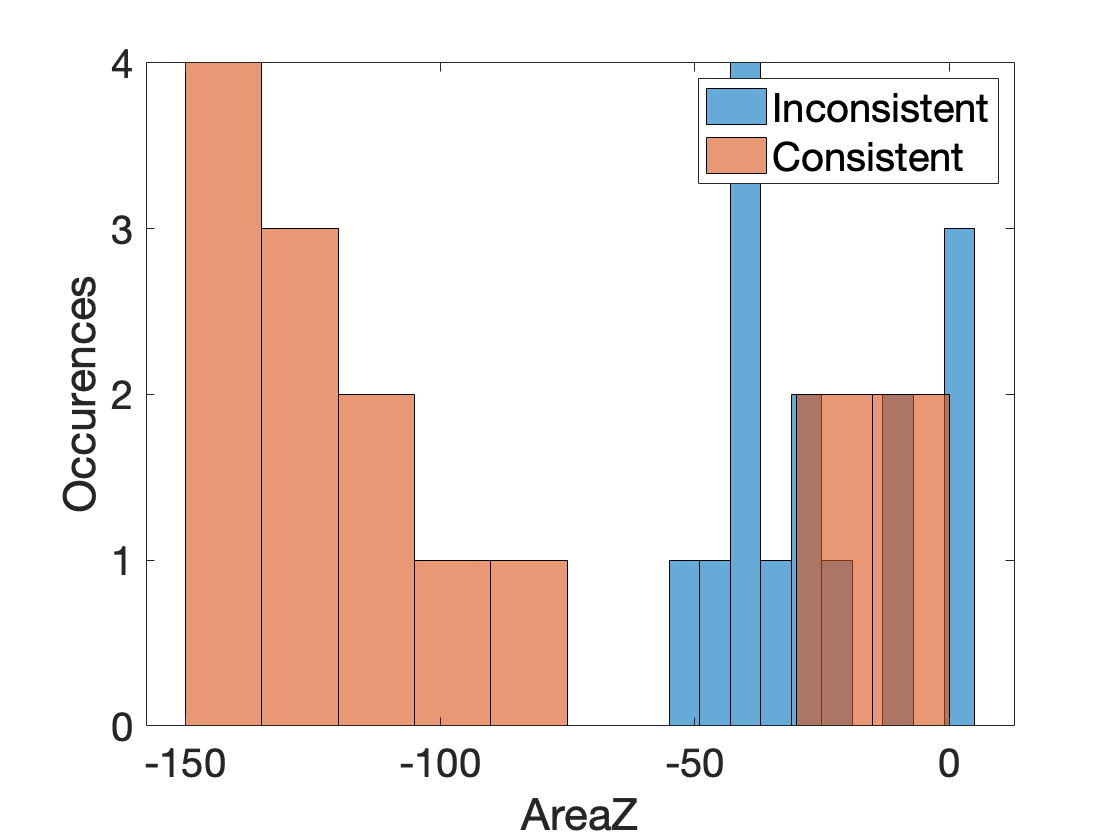

figure
histogram(BareaY,10)
hold on
histogram(GareaY,10)
xlabel('AreaZ','FontSize', 20); %x-axis label 
legend('Inconsistent', 'Consistent','FontSize', 20)
ylabel('Occurences','FontSize', 20); %y-axis label
set(gca,'FontSize',20)
hold off